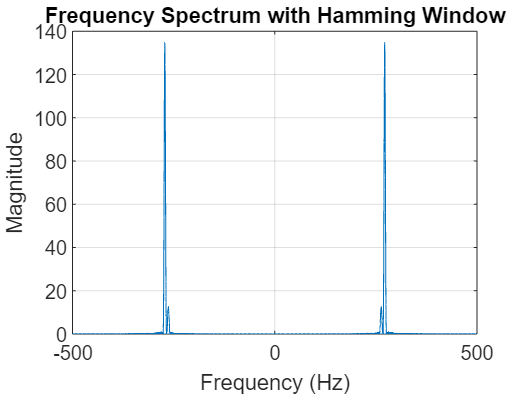


data = load('Exp4Data1.txt');


Fs = 1000; % Assume a value
N = length(data);


hamming_window = hamming(N);
windowed_signal = data .* transpose(hamming_window);


fft_result = fft(windowed_signal, 10000);
fft_result = fftshift(fft_result);  


frequencies = fftshift(-Fs/2:Fs/10000:Fs/2-Fs/10000);


figure;
plot(frequencies, abs(fft_result));
title('Frequency Spectrum with Hamming Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;



[peaks, peak_indices] = sort(abs(fft_result), 'descend');
freq1 = frequencies(peak_indices(1));
freq2 = frequencies(peak_indices(2));

fprintf('Frequency 1: %.3f Fs\n', freq1 / Fs);

Frequency 1: 0.272 Fs


fprintf('Frequency 2: %.3f Fs\n', freq2 / Fs);

Frequency 2: -0.272 Fs


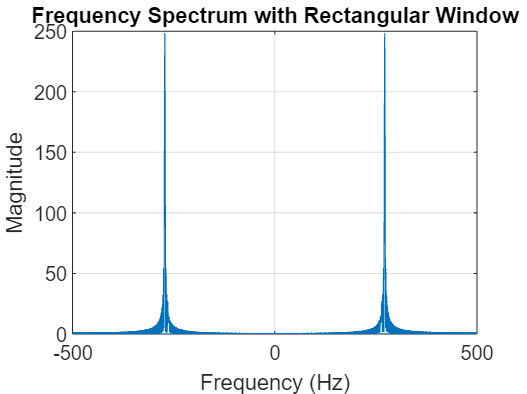



rectangular_window = ones(N, 1);
windowed_signal_rectangular = data .* transpose(rectangular_window);


fft_result_rectangular = fft(windowed_signal_rectangular, 10000);
fft_result_rectangular = fftshift(fft_result_rectangular);
frequencies_rectangular = fftshift(-Fs/2:Fs/10000:Fs/2-Fs/10000);


figure;
plot(frequencies_rectangular, abs(fft_result_rectangular));
title('Frequency Spectrum with Rectangular Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;



[peaks_rectangular, peak_indices_rectangular] = sort(abs(fft_result_rectangular), 'descend');
freq1_rectangular = frequencies_rectangular(peak_indices_rectangular(1));
freq2_rectangular = frequencies_rectangular(peak_indices_rectangular(2));

fprintf('Frequency 1 (Rectangular): %.3f Fs\n', freq1_rectangular / Fs);

Frequency 1 (Rectangular): 0.272 Fs


fprintf('Frequency 2 (Rectangular): %.3f Fs\n', freq2_rectangular / Fs);

Frequency 2 (Rectangular): -0.272 Fs
